# ******************************************************************************

# **DYNAMIC RESPONSE DUE TO EARTHQUAKE LOADING USING**

# **ASSUMED ACCELERATION METHODS**

# **"Constant (average) acceleration method"**

# ******************************************************************************

#### *Code established by : **Dr. Raouf Bencharif  * 

#### *                                      e-mail : *[rbencharif@cgsdz.org](http://rbencharif@cgsdz.org)

#### *                                     Researchgate : *[https://www.researchgate.net/profile/Raouf-Bencharif](https://www.researchgate.net/profile/Raouf-Bencharif)

####                                      Google Scholar : [https://scholar.google.com/citations?user=2ps9VqIAAAAJ](https://scholar.google.com/citations?user=2ps9VqIAAAAJ)

#### *Senior Researcher, at the National Center of Applied Research in Earthquake Engineering,CGS, (*[http://www.cgs-dz.org/index.php/fr/](http://www.cgs-dz.org/index.php/fr/))              

#### *Department of structural Dynamic Testing, *[http://www.cgs-dz.org/index.php/fr/laboratoires/un-laboratoire-d-essais-dynamiques-des-structures](http://www.cgs-dz.org/index.php/fr/laboratoires/un-laboratoire-d-essais-dynamiques-des-structures)              

## 1. Introduction

Figure 1.1 shows a SDOF system, with viscous damping and external forcing in schematic form. The mass $m$, is assumed to be excited directly by an external force, $p\left(t\right)$. The system will be assumed to be in equilibrium when the applied force is zero; any compression or extrusion of the spring due to gravity, for example, is assumed to have already taken plan, and can be ignored as far as the vibration response is concerned                 

 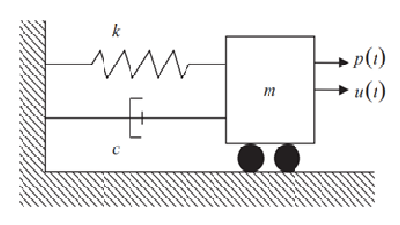

**Figure 1.1: SDOF System with Force Input**

The equation of motion governing the relative displacement  $u\left(t\right)$ of the linearly elastic structure is given by


$$m\ddot{u} +c\dot{u} +ku=p\left(t\right)$$


In the code, **Constant acceleration method** is employed for the numerical integration of the above equation. This method is versatile as it can handle irregular loading patterns, such as earthquake ground motion, and accommodate structures whose members transition from elastic to inelastic during response.

In this method a linear variation of acceleration from time $t_i$ to $t_{i+1}$ is assumed as illustrated the figure 1.2. Let $\tau$ denote the time within the interval $t_i$ and $t_{i+1}$ such that $0\le \tau \le \Delta t$ (see figure 1.2). Then acceleration at time τ is expressed as

 
$$\ddot{u} \left(\tau \right)=\frac{1}{2}\left({\ddot{u} }_{i+1} +{\ddot{u} }_j \right)$$


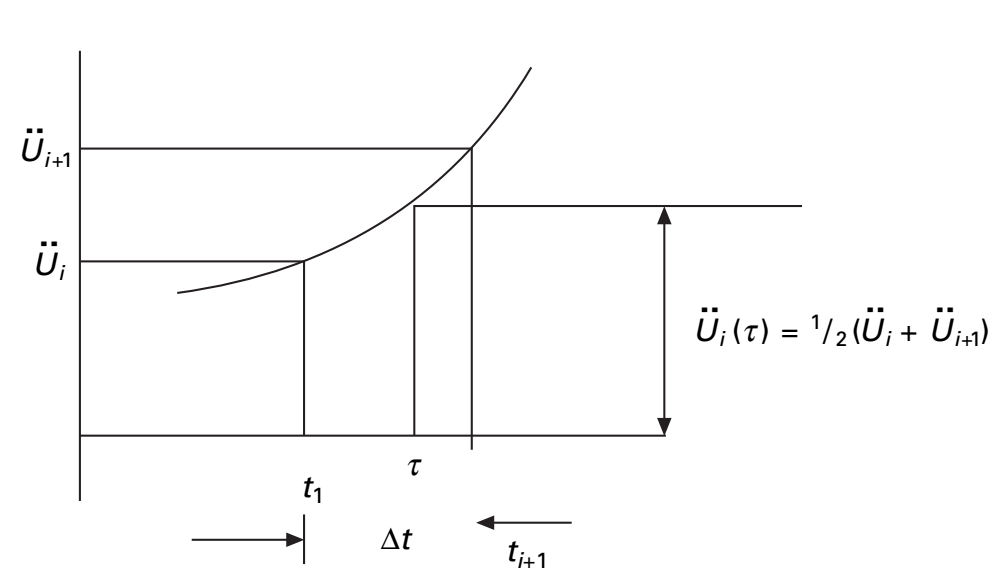

**Figure 1.2: Numerical integration using constant acceleration method**

## 2. Numerical Implementation of the "**Constant acceleration method"**

Pseudo-Code of the constant acceleration method

     A. Initial calculations

            1. Input $m,c,k,u_0 ,\omega_n ,\;{\dot{u} }_0 =v_0$ given

            2. Calculate ${\ddot{u} }_0$ from initial conditions as

                     
$$\left.\ddot{u} =\frac{1}{m}\left\lbrack p{\left(0\right)}-cv_0 -ku_0 \right\rbrack$$


            3.  Select the time step size $∆t$

            4. Calculate effective system

                      
$$\hat{k} =k+\frac{4m}{\Delta t^2 }+{\left(\frac{2c}{\Delta t}\right)}$$


     B. For each time step calculate effective incremental force

            1.       $\Delta \hat{p_i } =\Delta p_i +\left(\frac{4m}{\Delta t}+2c\right)\dot{u} +2m\ddot{u}$

            2. Solve for incremental displacement

                       
$$\Delta u_i =\frac{\Delta \hat{p_i } }{\hat{k} }$$


           3. Calculate incremental velocity and acceleration

                    
$$\Delta u_i =\left(\frac{2}{\Delta t}\right)\Delta u_i -2{\dot{u} }_i$$


                   
$$\Delta {\ddot{u} }_i =\frac{4}{\Delta t^2 }\left(\Delta u_i -\Delta t{\dot{u} }_i \right)-2{\ddot{u} }_i$$


             4. Calculate displacements, velocity and acceleration at time … as

                    
$$u_{i+1} =u_i +\Delta u_i$$


                    
$${\dot{u} }_{i+1} ={\dot{u} }_i +\Delta {\dot{u} }_i$$


                    
$${\ddot{u} }_{i+1} ={\ddot{u} }_i +\Delta {\ddot{u} }_i$$


If the excitation is ground acceleration ${\ddot{u} }_g \left(t\right)$replace $p_i$ by ${-m\;\ddot{u} }_{\textrm{gi}}$ where in this case ui, ˙ui,and ¨ui give response values relative to the ground.

The computed $u_i$, ${\dot{u} }_i$ , and ${\ddot{u} }_i$ give response values relative to the ground. If needed, the total velocity and acceleration can be computed readily: ${\dot{u} }_i^t ={\dot{u} }_i +{\dot{u} }_{gi}$ and ${\ddot{u} }_i^t ={\ddot{u} }_i +{\ddot{u} }_{gi}$

The Linear acceleration method  will “blow up,” giving meaningless results, in the presence of numerical round-off if the time step chosen is not short enough. The specific requirement for stability is

                                                                                                                
$$\Delta t<\frac{T}{10}$$


It can be proved that the constant acceleration method is equivalent to the trapezoidal rule. It is also a special form of the Newmark method.

## *3. Reference *

Chopra, Anil K. (2011), Dynamics Structures: Theory and Applications to Earthquake Engineering, 4th Edition, Prentice Hall, New Jersey.

Rajasekaran, S. (2009). *Structural dynamics of earthquake engineering: theory and application using MATHEMATICA and MATLAB*. Elsevier.

RAY, W. Clough et JOSEPH, Penzien (2003). Dynamics of structures. *Computers & Structures, Berkeley, CA, USA*.

## 4. Input motion

clear all;clc;
load KOBE.txt                % Accelerqtion time history 
g=9.8;                       % Gravity                    [m/s²]
t=KOBE(:,1);                 % Time                       [s]
Ag=KOBE(:,2)*g;              % Acceleration               [m/s²]       
dt= t(2)-t(1);               % Time interval              [s]
At=KOBE;

## 5. Plot input motion

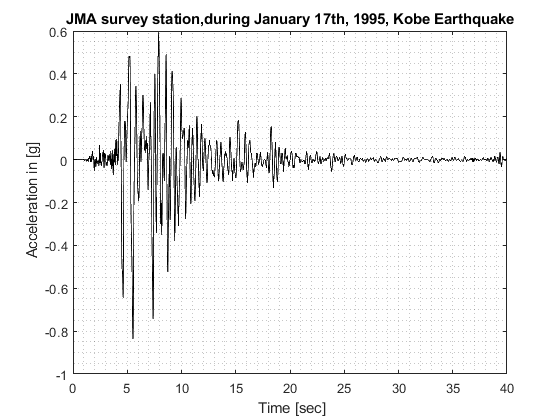

plot(t,Ag/g,'k');xlabel(' Time [sec]');
              ylabel(' Acceleration in [g]');
              title('JMA survey station,during January 17th, 1995, Kobe Earthquake');grid minor;

## 6. Characteristics of the SDOF system

m=120;                       % Mass                      [Ton]
T=0.4;                       % Period                    [seconds]
k=m*(2*pi/T)^2;              % Stiffness                 [KN]
zeta =0.05;                  % Critical damping Ratio    [%]
wn=sqrt(k/m);                % Circular frequency        [rad/s]
c=2*m*wn*zeta;               % Damping value             [KN s/m]

## 7. Check of stability condition

if dt/T<1/pi
    display('The solution is stable')
else
    display('The solution is not stable')
end

The solution is stable


## 8. Vector force  

P=-m*Ag;                      % Load vector              [KN]

## 9. Initial calculations


u(1)=0;
v(1)=0;


## 10. Calculation process

an(1)=(P(1)-c*v(1)-k*u(1))/m;
kh=k+4.0*m/(dt*dt)+2.0*c/dt;

for i=2:length(P)
    ww=P(i)-P(i-1)+(4.0*m/dt+2.0*c)*v(i-1)+2.0*m*an(i-1);
    xx=ww/kh;
    yy=(2/dt)*xx-2.0*v(i-1);
    zz=(4.0/(dt*dt))*(xx-dt*v(i-1))-2.0*an(i-1);
    u(i)=u(i-1)+xx;
    v(i)=v(i-1)+yy;
    an(i)=an(i-1)+zz;
end

## 11. Plot responses

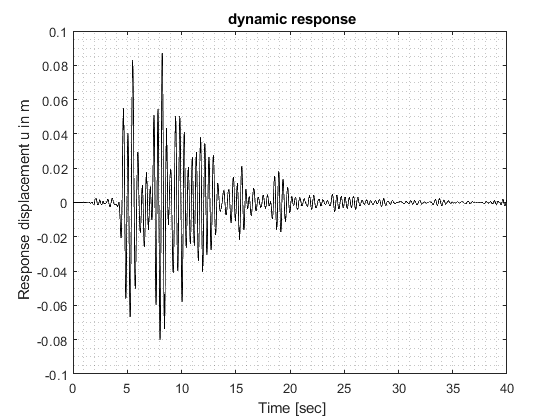



plot(t,u,'k');xlabel(' Time [sec]');
              ylabel(' Response displacement u in m');
              title(' dynamic response');grid minor;

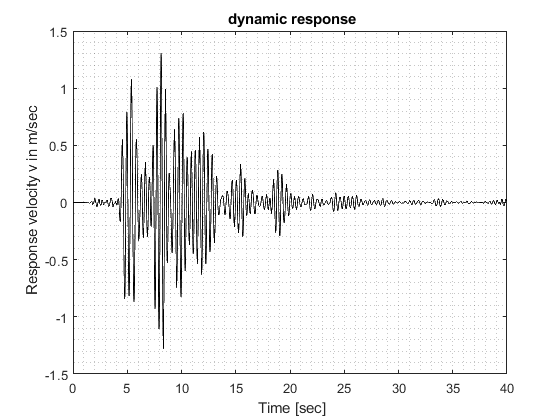


plot(t,v,'k');xlabel(' Time [sec]');
              ylabel(' Response velocity v in m/sec');
              title(' dynamic response');grid minor;